# Collect and process all simulation results

clear;
clc;
close all;

## Read the number of relays used in each case with a fixed beamwidth B

relayNum1 = '1152';
relayNum2 = '2384';
pathname = '../../Data/Paths/';
pathnameidp = '../../Data/Paths/Idp/';
listing = dir(pathname);
files = listing(3:end-2);
filenames = strings(size(files));
name_1_5 = [];
name_1_7 = [];
name_1_9 = [];
name_1_11 = [];
name_1_13 = [];
name_1_15 = [];
name_2_5 = [];
name_2_7 = [];
name_2_9 = [];
name_2_11 = [];
name_2_13 = [];
name_2_15 = [];
pathNum_name_1_5 = [];
pathNum_name_1_7 = [];
pathNum_name_1_9 = [];
pathNum_name_1_11 = [];
pathNum_name_1_13 = [];
pathNum_name_1_15 = [];
pathNum_name_2_5 = [];
pathNum_name_2_7 = [];
pathNum_name_2_9 = [];
pathNum_name_2_11 = [];
pathNum_name_2_13 = [];
pathNum_name_2_15 = [];
for i = 1:length(files)
   filenames(i) = files(i).name;
   strs = strsplit(filenames(i),'.');
   name = strs(1);
   paras = strsplit(name,'_');
   if (paras(6) == '5' && paras(7) == 'Sequence' && paras(4) == relayNum1)
       name_1_5 = [name_1_5;name];
       pathNum_name_1_5 = [pathNum_name_1_5; str2num(paras(5))];
   end
   if (paras(6) == '7' && paras(7) == 'Sequence' && paras(4) == relayNum1)
       name_1_7 = [name_1_7;name];
       pathNum_name_1_7 = [pathNum_name_1_7; str2num(paras(5))];
   end
   if (paras(6) == '9' && paras(7) == 'Sequence' && paras(4) == relayNum1)
       name_1_9 = [name_1_9;name];
       pathNum_name_1_9 = [pathNum_name_1_9; str2num(paras(5))];
   end
   if (paras(6) == '11' && paras(7) == 'Sequence' && paras(4) == relayNum1)
       name_1_11 = [name_1_11;name];
       pathNum_name_1_11 = [pathNum_name_1_11; str2num(paras(5))];
   end
   if (paras(6) == '13' && paras(7) == 'Sequence' && paras(4) == relayNum1)
       name_1_13 = [name_1_13;name];
       pathNum_name_1_13 = [pathNum_name_1_13; str2num(paras(5))];
   end
   if (paras(6) == '15' && paras(7) == 'Sequence' && paras(4) == relayNum1)
       name_1_15 = [name_1_15;name];
       pathNum_name_1_15 = [pathNum_name_1_15; str2num(paras(5))];
   end
   if (paras(6) == '5' && paras(7) == 'Sequence' && paras(4) == relayNum2)
       name_2_5 = [name_2_5;name];
       pathNum_name_2_5 = [pathNum_name_2_5; str2num(paras(5))];
   end
   if (paras(6) == '7' && paras(7) == 'Sequence' && paras(4) == relayNum2)
       name_2_7 = [name_2_7;name];
       pathNum_name_2_7 = [pathNum_name_2_7; str2num(paras(5))];
   end
   if (paras(6) == '9' && paras(7) == 'Sequence' && paras(4) == relayNum2)
       name_2_9 = [name_2_9;name];
       pathNum_name_2_9 = [pathNum_name_2_9; str2num(paras(5))];
   end
   if (paras(6) == '11' && paras(7) == 'Sequence' && paras(4) == relayNum2)
       name_2_11 = [name_2_11;name];
       pathNum_name_2_11 = [pathNum_name_2_11; str2num(paras(5))];
   end
   if (paras(6) == '13' && paras(7) == 'Sequence' && paras(4) == relayNum2)
       name_2_13 = [name_2_13;name];
       pathNum_name_2_13 = [pathNum_name_2_13; str2num(paras(5))];
   end
   if (paras(6) == '15' && paras(7) == 'Sequence' && paras(4) == relayNum2)
       name_2_15 = [name_2_15;name];
       pathNum_name_2_15 = [pathNum_name_2_15; str2num(paras(5))];
   end
end

numRelay_1_5 = zeros(length(name_1_5),1);
numRelay_1_7 = zeros(length(name_1_7),1);
numRelay_1_9 = zeros(length(name_1_9),1);
numRelay_1_11 = zeros(length(name_1_11),1);
numRelay_1_13 = zeros(length(name_1_13),1);
numRelay_1_15 = zeros(length(name_1_15),1);
numRelay_1_5_idp = zeros(length(name_1_5),1);
numRelay_1_7_idp = zeros(length(name_1_7),1);
numRelay_1_9_idp = zeros(length(name_1_9),1);
numRelay_1_11_idp = zeros(length(name_1_11),1);
numRelay_1_13_idp = zeros(length(name_1_13),1);
numRelay_1_15_idp = zeros(length(name_1_15),1);
for i = 1:length(name_1_5)
    filename = pathname + name_1_5(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_5(i)]);
    numRelay_1_5(i) = data(2,end);
    fclose(fileID);
%     filename = pathnameidp + name_1_5(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_1_5(i)]);
%     numRelay_1_5_idp(i) = data(2,end);
%     fclose(fileID);
end
for i = 1:length(name_1_7)
    filename = pathname + name_1_7(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_7(i)]);
    numRelay_1_7(i) = data(2,end);
    fclose(fileID);
%     filename = pathnameidp + name_1_7(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_1_7(i)]);
%     numRelay_1_7_idp(i) = data(2,end);
%     fclose(fileID);
end
for i = 1:length(name_1_9)
    filename = pathname + name_1_9(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_9(i)]);
    numRelay_1_9(i) = data(2,end);
    fclose(fileID);
%     filename = pathnameidp + name_1_9(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_1_9(i)]);
%     numRelay_1_9_idp(i) = data(2,end);
%     fclose(fileID);
end
for i = 1:length(name_1_11)
    filename = pathname + name_1_11(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_11(i)]);
    numRelay_1_11(i) = data(2,end);
    fclose(fileID);
%     filename = pathnameidp + name_1_11(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_1_11(i)]);
%     numRelay_1_11_idp(i) = data(2,end);
%     fclose(fileID);
end
for i = 1:length(name_1_13)
    filename = pathname + name_1_13(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_13(i)]);
    numRelay_1_13(i) = data(2,end);
    fclose(fileID);
%     filename = pathnameidp + name_1_13(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_1_13(i)]);
%     numRelay_1_13_idp(i) = data(2,end);
%     fclose(fileID);
end
for i = 1:length(name_1_15)
    filename = pathname + name_1_15(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_1_15(i)]);
    numRelay_1_15(i) = data(2,end);
    fclose(fileID);
%     filename = pathnameidp + name_1_15(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_1_15(i)]);
%     numRelay_1_15_idp(i) = data(2,end);
%     fclose(fileID);
end

avgNumRelay_1_5 = numRelay_1_5./pathNum_name_1_5;
avgNumRelay_1_7 = numRelay_1_7./pathNum_name_1_7;
avgNumRelay_1_9 = numRelay_1_9./pathNum_name_1_9;
avgNumRelay_1_11 = numRelay_1_11./pathNum_name_1_11;
avgNumRelay_1_13 = numRelay_1_13./pathNum_name_1_13;
avgNumRelay_1_15 = numRelay_1_15./pathNum_name_1_15;
% avgNumRelay_1_5_idp = numRelay_1_5_idp./pathNum_name_1_5;
% avgNumRelay_1_7_idp = numRelay_1_7_idp./pathNum_name_1_7;
% avgNumRelay_1_9_idp = numRelay_1_9_idp./pathNum_name_1_9;
% avgNumRelay_1_11_idp = numRelay_1_11_idp./pathNum_name_1_11;
% avgNumRelay_1_13_idp = numRelay_1_13_idp./pathNum_name_1_13;
% avgNumRelay_1_15_idp = numRelay_1_15_idp./pathNum_name_1_15;
mean(avgNumRelay_1_5)

ans = 1.0353

% mean(avgNumRelay_1_5_idp)
mean(avgNumRelay_1_7)

ans = 1.0706

% mean(avgNumRelay_1_7_idp)
mean(avgNumRelay_1_9)

ans = 1.1164

% mean(avgNumRelay_1_9_idp)
mean(avgNumRelay_1_11)

ans = 1.1657

% mean(avgNumRelay_1_11_idp)
mean(avgNumRelay_1_13)

ans = 1.2286

% mean(avgNumRelay_1_13_idp)
mean(avgNumRelay_1_15)

ans = 1.3036

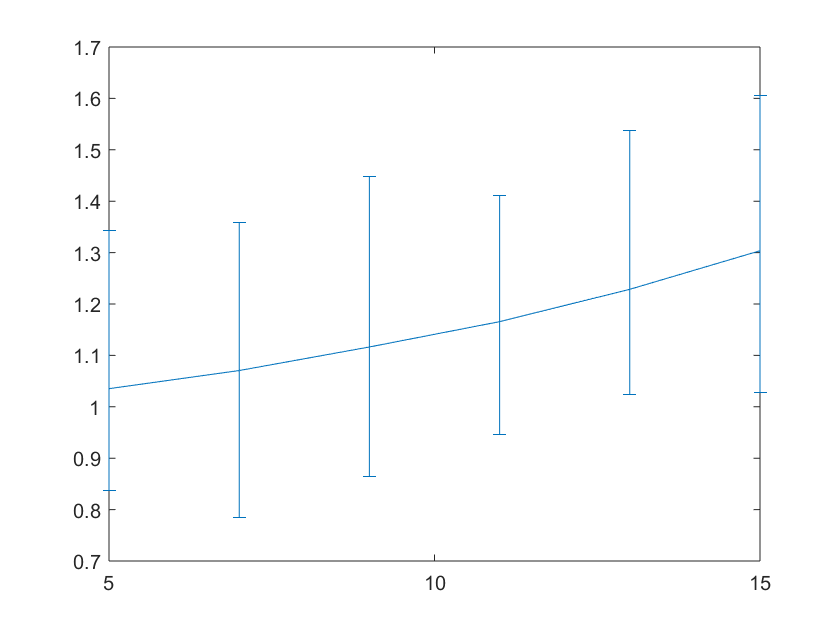

% mean(avgNumRelay_1_15_idp)
figure;
bw = 5:2:15;
avgNumRelay = [mean(avgNumRelay_1_5), mean(avgNumRelay_1_7), mean(avgNumRelay_1_9), mean(avgNumRelay_1_11), mean(avgNumRelay_1_13), mean(avgNumRelay_1_15)];
avgNumRelayMin = avgNumRelay - [min(avgNumRelay_1_5), min(avgNumRelay_1_7), min(avgNumRelay_1_9), min(avgNumRelay_1_11), min(avgNumRelay_1_13), min(avgNumRelay_1_15)];
avgNumRelayMax = [max(avgNumRelay_1_5), max(avgNumRelay_1_7), max(avgNumRelay_1_9), max(avgNumRelay_1_11), max(avgNumRelay_1_13), max(avgNumRelay_1_15)] - avgNumRelay;
errorbar(bw,avgNumRelay,avgNumRelayMin,avgNumRelayMax); hold on;

% avgNumRelayIdp = [mean(avgNumRelay_1_5_idp), mean(avgNumRelay_1_7_idp), mean(avgNumRelay_1_9_idp), mean(avgNumRelay_1_11_idp), mean(avgNumRelay_1_13_idp), mean(avgNumRelay_1_15_idp)];
% avgNumRelayMinIdp = avgNumRelay - [min(avgNumRelay_1_5_idp), min(avgNumRelay_1_7_idp), min(avgNumRelay_1_9_idp), min(avgNumRelay_1_11_idp), min(avgNumRelay_1_13_idp), min(avgNumRelay_1_15_idp)];
% avgNumRelayMaxIdp = [max(avgNumRelay_1_5_idp), max(avgNumRelay_1_7_idp), max(avgNumRelay_1_9_idp), max(avgNumRelay_1_11_idp), max(avgNumRelay_1_13_idp), max(avgNumRelay_1_15_idp)] - avgNumRelay;
% errorbar(bw,avgNumRelayIdp,avgNumRelayMinIdp,avgNumRelayMaxIdp);
numRelay_2_5 = zeros(length(name_2_5),1);
numRelay_2_7 = zeros(length(name_2_7),1);
numRelay_2_9 = zeros(length(name_2_9),1);
numRelay_2_11 = zeros(length(name_2_11),1);
numRelay_2_13 = zeros(length(name_2_13),1);
numRelay_2_15 = zeros(length(name_2_15),1);
for i = 1:length(name_2_5)
    filename = pathname + name_2_5(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_5(i)]);
    numRelay_2_5(i) = data(2,end);
    fclose(fileID);
%     filename = pathnameidp + name_2_5(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_2_5(i)]);
%     numRelay_2_5_idp(i) = data(2,end);
%     fclose(fileID);
end
for i = 1:length(name_2_7)
    filename = pathname + name_2_7(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_7(i)]);
    numRelay_2_7(i) = data(2,end);
    fclose(fileID);
%     filename = pathnameidp + name_2_7(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_2_7(i)]);
%     numRelay_2_7_idp(i) = data(2,end);
%     fclose(fileID);
end
for i = 1:length(name_2_9)
    filename = pathname + name_2_9(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_9(i)]);
    numRelay_2_9(i) = data(2,end);
    fclose(fileID);
%     filename = pathnameidp + name_2_9(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_2_9(i)]);
%     numRelay_2_9_idp(i) = data(2,end);
%     fclose(fileID);
end
for i = 1:length(name_2_11)
    filename = pathname + name_2_11(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_11(i)]);
    numRelay_2_11(i) = data(2,end);
    fclose(fileID);
%     filename = pathnameidp + name_2_11(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_2_11(i)]);
%     numRelay_2_11_idp(i) = data(2,end);
%     fclose(fileID);
end
for i = 1:length(name_2_13)
    filename = pathname + name_2_13(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_13(i)]);
    numRelay_2_13(i) = data(2,end);
    fclose(fileID);
%     filename = pathnameidp + name_2_13(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_2_13(i)]);
%     numRelay_2_13_idp(i) = data(2,end);
%     fclose(fileID);
end
for i = 1:length(name_2_15)
    filename = pathname + name_2_15(i) + '.txt';
    fileID = fopen(filename,'r');
    data = fscanf(fileID,'%d %d',[2,pathNum_name_2_15(i)]);
    numRelay_2_15(i) = data(2,end);
    fclose(fileID);
%     filename = pathnameidp + name_2_15(i) + '.txt';
%     fileID = fopen(filename,'r');
%     data = fscanf(fileID,'%d %d',[2,pathNum_name_2_15(i)]);
%     numRelay_2_15_idp(i) = data(2,end);
%     fclose(fileID);
end

avgNumRelay_2_5 = numRelay_2_5./pathNum_name_2_5; mean(avgNumRelay_2_5)

ans = 0.9375

avgNumRelay_2_7 = numRelay_2_7./pathNum_name_2_7; mean(avgNumRelay_2_7)

ans = 0.9793

avgNumRelay_2_9 = numRelay_2_9./pathNum_name_2_9; mean(avgNumRelay_2_9)

ans = 0.9951

avgNumRelay_2_11 = numRelay_2_11./pathNum_name_2_11; mean(avgNumRelay_2_11)

ans = 1.0487

avgNumRelay_2_13 = numRelay_2_13./pathNum_name_2_13; mean(avgNumRelay_2_13)

ans = 1.0807

avgNumRelay_2_15 = numRelay_2_15./pathNum_name_2_15; mean(avgNumRelay_2_15)

ans = 1.1674